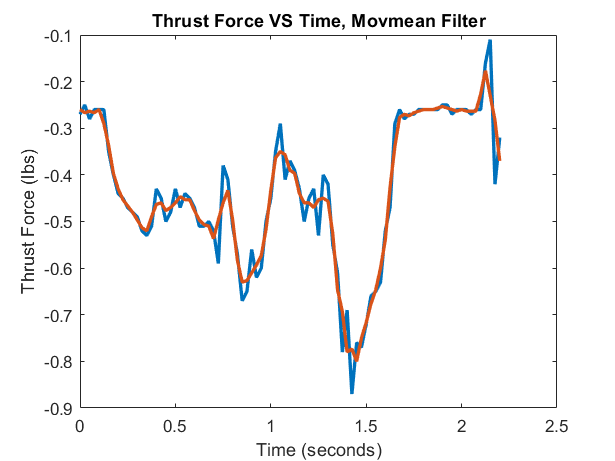

clc;
close all;
clear all;
clearvars;

% import the data from the text file

data_file = sprintf('testdata.mat');
data = importdata(data_file);
start = 1;

% Get the time, theta, and dtheta from arduino code
datatime = data(start+1:end, 1); %useless
thrustforce = data(start+1:end, 2); 
encoder1angle = data(start+1:end, 3);
encoder2angle = data(start+1:end, 4);

% Define sampling frequency and time vector
fs = 40;  % Hz 
time = (0:length(thrustforce)-1)/fs; 

%movmean converted data vectors

newthrustforce_movmean = movmean(thrustforce,3); %% moving average last three
newencoder2angle_movmean = movmean(encoder2angle,3);
newencoder1angle_movmean = movmean(encoder1angle, 3);

%Movmean Filter (type of builtin moving average)

figure(1);
plot(time, thrustforce, 'LineWidth',2);
hold on;
plot(time, newthrustforce_movmean,'LineWidth',2);
title("Thrust Force VS Time, Movmean Filter");
ylabel('Thrust Force (lbs)');
xlabel('Time (seconds)');
hold off;

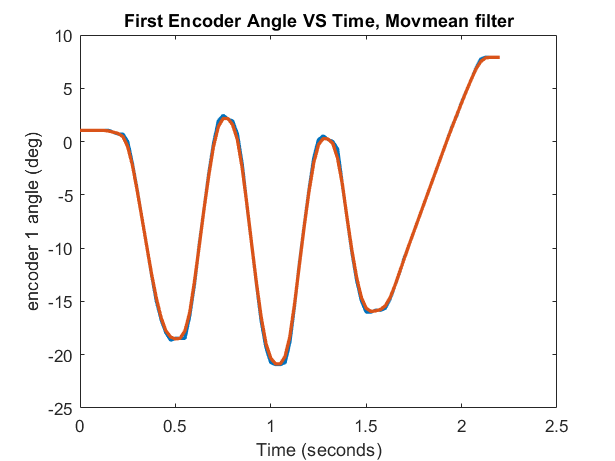


figure(2);
plot(time, encoder1angle, 'LineWidth',2);
hold on;
plot(time, newencoder1angle_movmean, 'LineWidth',2);
title("First Encoder Angle VS Time, Movmean filter");
ylabel('encoder 1 angle (deg)');
xlabel('Time (seconds)');
hold off;

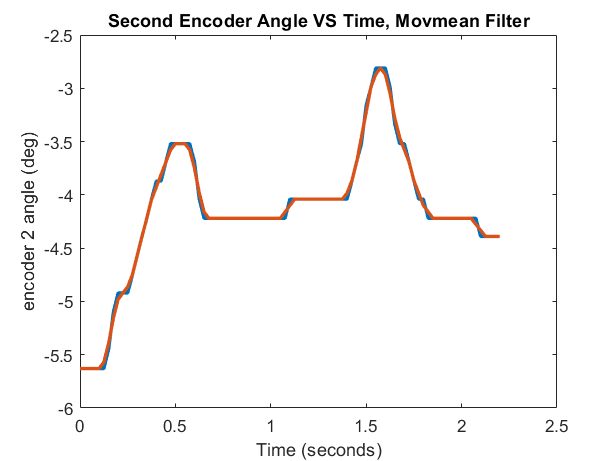


figure(3);
plot(time, encoder2angle, 'LineWidth',2);
hold on;
plot(time, newencoder2angle_movmean, 'LineWidth',2);
title("Second Encoder Angle VS Time, Movmean Filter");
ylabel('encoder 2 angle (deg)');
xlabel('Time (seconds)');
hold off;


%CALCULATE MMOI

%encoder_data = load('encoder_data.txt'); (use if encoder data is in a
%separate file for this test (it will be eventually)

% Extract the position data from the encoder data
position = newencoder1angle_movmean;

%new time variable declared because this is a separate test

%N = length(position);
%mmoi_time = (0:N-1) / fs; % Sampling rate is 80Hz
%
% Calculate the period of the cylinder's oscillation
%period = calculate_period(mmoi_time, position); 

%Mass (kg)
%m = 1.5; 

%Length (m)
%L = 0.5;

%Inertia
%I = (m * L^2) / (4 * pi^2 * period^2);

% Print value
%fprintf('The mass moment of inertia of the cylinder is: %f kg*m^2\n', I);

% Define the function to calculate the period

% FINDING THE TRANSFER FUNCTION

impulse_hammer_data_file = sprintf('Impulse_Data_Recent.mat');
hammer_data = importdata(impulse_hammer_data_file);

desired_frequency = 80; %Hz, (sampling rate of slowest 
sampling_rate = 1000000 %Hz (look at oscilloscope SPS rate)

sampling_rate = 1000000

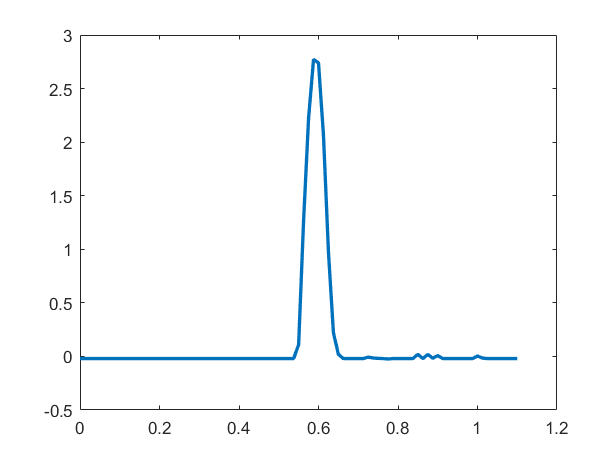

downsampling_factor = round(sampling_rate / 80); 

if length(hammer_data)/downsampling_factor < length(data) % must resample then downsample (otherwise will give less than n number of pts)
    upsampling_factor = (length(data) +(floor((length(data)*downsampling_factor)/length(hammer_data))-length(data)))-1; %% upsample hammer data
    upsampled_hammer_data = resample(hammer_data, upsampling_factor, 1);
    downsampled_hammer_data = downsample(upsampled_hammer_data, downsampling_factor);  %downsample to match 80HZ
else %dont need to resample, just downsample
    downsampled_hammer_data = downsample(hammer_data, downsampling_factor);  %downsample to match 80HZ
end

figure(5); % plot impact hammer wave
hammer_time = (0:length(downsampled_hammer_data)-1)/80;
plot(hammer_time, downsampled_hammer_data, 'LineWidth',2);


save("downsampled_hammer_data.mat"); %save file

% Design a low-pass filter for the encoder signals
fc = 30; % Hz (Nyquist Frequency)
[b,a] = butter(1, fc/(fs/2), "low");

Error using butter>butterImpl
The cutoff frequencies must be within the interval of (0,1).

Error in butter (line 59)
   [varargout{1:nargout}] = butterImpl(n,Wn,varargin{:});


% Apply the filter to the encoder signals and hammer signal 
hammer_filt = filtfilt(b,a,downsampled_hammer_data);

y1_filt = filtfilt(b,a,newencoder1angle_movmean);
y2_filt = filtfilt(b,a,newencoder2angle_movmean);

% Define the input and output signals with filtered encoder data

y1_filt = iddata(y1_filt, hammer_filt, 1/fs);
y2_filt = iddata(y2_filt, hammer_filt, 1/fs);

% Specify the model structure
sys1 = tfest(y1_filt, 2, 0); %lowest order that caputres order well enough
sys2 = tfest(y2_filt, 2, 0);

% Plot the Bode plot of the transfer function
bode(sys1);
bode(sys2);

disp(sys1);
disp(sys2);

step(sys1)
step(sys2)

grid on;


function period = calculate_period(time, position)
    % Find the time of the first peak
    [~, index] = max(position);
    t1 = time(index);

    % time of the second peak
    [~, index] = max(position(index+1:end));
    t2 = time(index+length(time)/2);

    % Calculate period
    period = t2 - t1;
end